f = @(w) 0.4 .* w.^2 + 4 .* w + 11;

W = linspace(-20,20,1000);

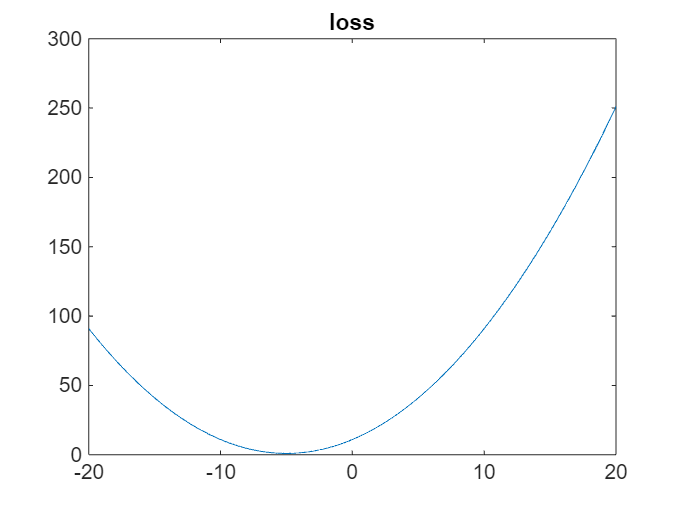

plot(W,f(W))
title("loss")

df = @(w) 0.8 .* w + 4;
d2f = @(w) 0.8 ;

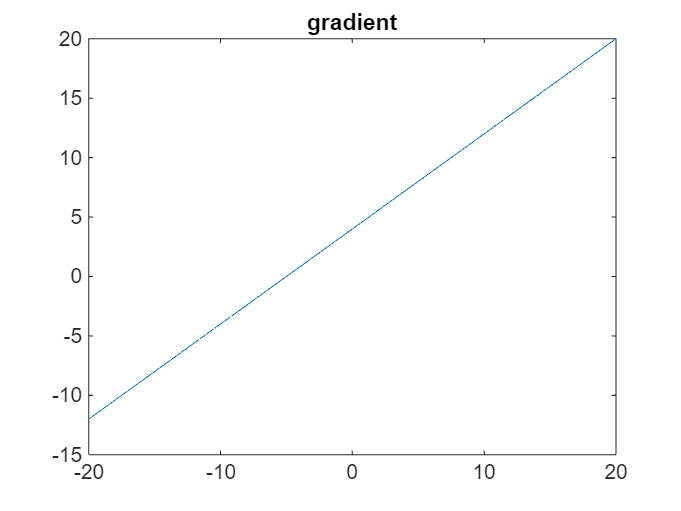

plot(W,df(W))
title("gradient")

function w = SD(w0, mu, df, eps)
    max_iter = 1000;
    w = zeros(1, max_iter); 
    
    % Initialize
    w(1) = w0;
    k = 1;
    converged = false;

    while (k < max_iter)
        % 2. Calculate the next step (Minimization is '-' mu * df)
        gradient = df(w(k));
        next_w = w(k) - mu * gradient;
        
        % 3. Check for convergence BEFORE assigning to the array
        if abs(next_w - w(k)) < eps
            w(k+1) = next_w;
            k = k + 1;
            converged = true;
            break; 
        end
        
        % Store and increment
        w(k+1) = next_w;
        k = k + 1;
    end
    w = w(1:k);
    
    if ~converged
        warning('Algorithm reached max iterations without converging.');
    end
end

w0=0;
mu = 1.5;
eps = 1e-5;
w_SD = SD(w0,mu,df,eps)

w_SD =          0   -6.0000   -4.8000   -5.0400   -4.9920   -5.0016   -4.9997   -5.0001   -5.0000   -5.0000   -5.0000


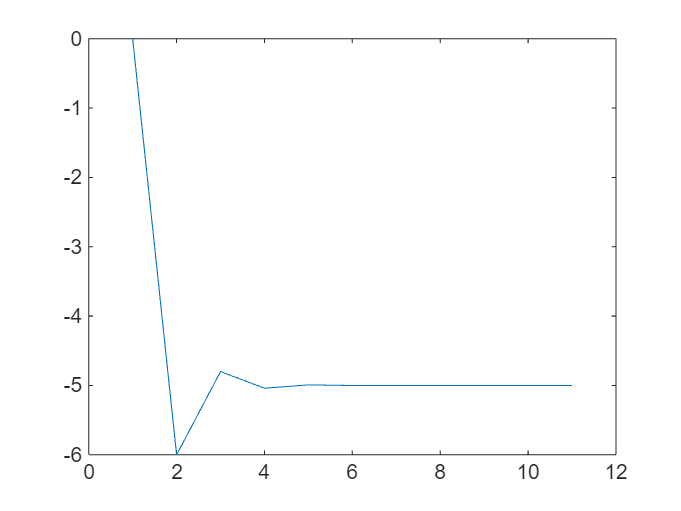

plot(1:length(w_SD),w_SD)

function w = Newton(w0, df, d2f, eps)
    max_iter = 1000;
    w = zeros(1, max_iter); 
    
    % Initialize
    w(1) = w0;
    k = 1;
    converged = false;

    while (k < max_iter)
        % 2. Calculate the next step 
        next_w = w(k) - df(w(k))/d2f(w(k));
        
        % 3. Check for convergence BEFORE assigning to the array
        if abs(next_w - w(k)) < eps
            w(k+1) = next_w;
            k = k + 1;
            converged = true;
            break; 
        end
        
        % Store and increment
        w(k+1) = next_w;
        k = k + 1;
    end
    w = w(1:k);
    
    if ~converged
        warning('Algorithm reached max iterations without converging.');
    end
end

w0 = 0;
mu = 1.5;
eps = 1e-5;

w_Newton = Newton(w0,df,d2f,eps)

w_Newton =      0    -5    -5


w_SD= SD(w0,mu,df,eps)

w_SD =          0   -6.0000   -4.8000   -5.0400   -4.9920   -5.0016   -4.9997   -5.0001   -5.0000   -5.0000   -5.0000


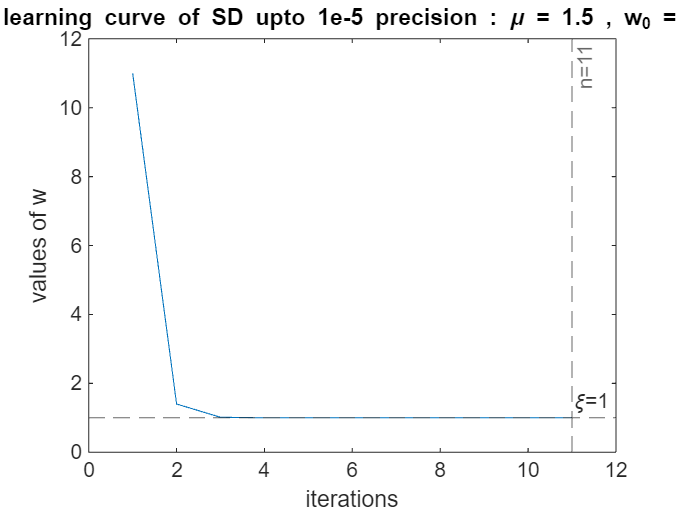

plot(1:length(w_SD),f(w_SD))
title("learning curve of SD upto 1e-5 precision : \mu = 1.5 , w_0 = 0")
xlabel("iterations")
ylabel("values of w")
yline(1,'--',"\xi=1")
xline(11,'--',"n=11")

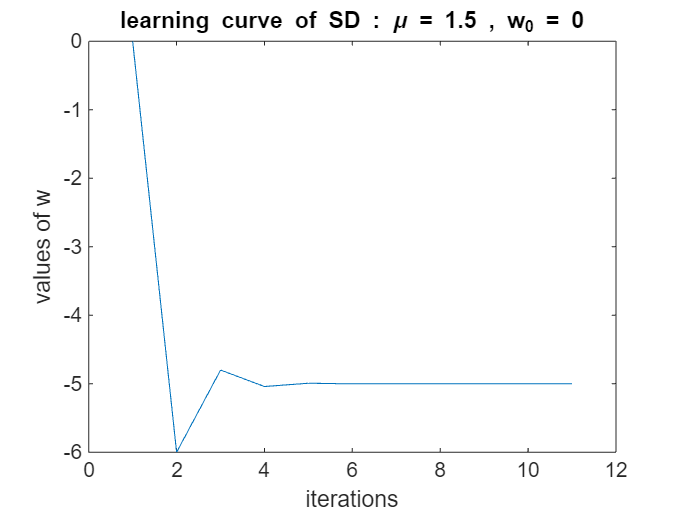


plot(1:length(w_SD),w_SD)
title("learning curve of SD : \mu = 1.5 , w_0 = 0")
xlabel("iterations")
ylabel("values of w")

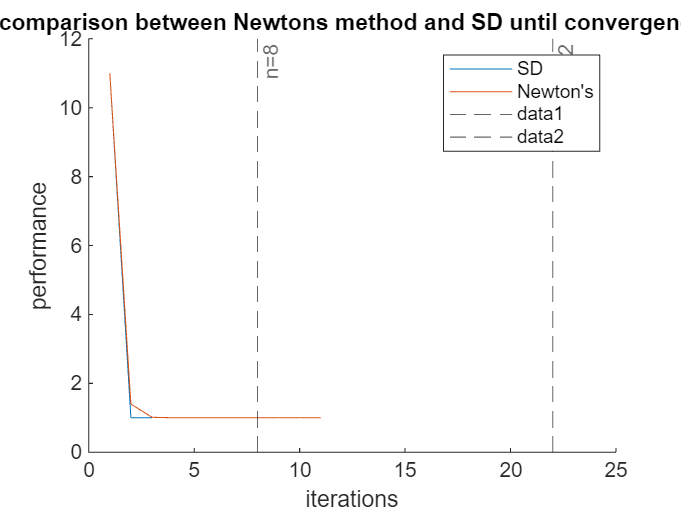

figure;
hold on ;

plot(1:length(w_Newton),f(w_Newton))
plot(1:length(w_SD),f(w_SD))

legend("SD","Newton's")
title("comparison between Newtons method and SD until convergence")
xlabel("iterations")
ylabel("performance")
xline(8,"--","n=8")
xline(22,"--","n=22")
hold off ; 

**2.g**

mu = 0.05;
w0 = 0;

g = @(w) 42 + w' * [[2,1];[1,2]] * w - 2 * [7;8]' * w ;

dg = @(w) 2 * [[2,1];[1,2]] * w - 2 * [7;8] ;

d2g = @(w) 2 * [[2,1];[1,2]] ;

% Wrap the function to apply it to each column of the input matrix
g_vec = @(W) arrayfun(@(i) g(W(:,i)), 1:size(W,2));

% Test it:
result = g_vec(zeros(2,5)) % Returns: [42, 42, 42, 42, 42]

result =     42    42    42    42    42


we rewrite the equation to support matrices :

function w = Newton_M(w0, df, d2f, mu, eps)
    max_iter = 1000;
    
    % Ensure w0 is a column vector for consistency
    w0 = w0(:); 
    dim = length(w0);
    
    % Preallocate: rows = dimensions, columns = iterations
    w = zeros(dim, max_iter); 
    
    % Initialize
    w(:, 1) = w0;
    k = 1;
    converged = false;

    while (k < max_iter)
        current_w = w(:, k);
        
        % Calculate the next step using the backslash operator
        % Works for Matrix (Hessian \ Gradient) and Scalar (f'' \ f')
        step = d2f(current_w) \ df(current_w);
        next_w = current_w - mu*step;
        
        % Check for convergence using the norm (magnitude of the step)
        if norm(next_w - current_w) < eps
            w(:, k+1) = next_w;
            k = k + 1;
            converged = true;
            break; 
        end
        
        % Store and increment
        w(:, k+1) = next_w;
        k = k + 1;
    end
    
    % Trim unused preallocated columns
    w = w(:, 1:k);
    
    if ~converged
        warning('Algorithm reached max iterations without converging.');
    end
end

function w = SD_M(w0, mu, df, eps)
    max_iter = 1000;
    
    % Ensure w0 is a column vector
    w0 = w0(:);
    dim = length(w0);
    
    % Preallocate: rows = dimensions, columns = iterations
    w = zeros(dim, max_iter); 
    
    % Initialize
    w(:, 1) = w0;
    k = 1;
    converged = false;

    while (k < max_iter)
        current_w = w(:, k);
        
        % 2. Calculate the next step (Gradient Descent)
        gradient = df(current_w);
        next_w = current_w - mu * gradient;
        
        % 3. Check for convergence using the norm of the step
        if norm(next_w - current_w) < eps
            w(:, k+1) = next_w;
            k = k + 1;
            converged = true;
            break; 
        end
        
        % Store and increment
        w(:, k+1) = next_w;
        k = k + 1;
    end
    
    % Trim unused columns
    w = w(:, 1:k);
    
    if ~converged
        warning('Algorithm reached max iterations without converging.');
    end
end

w0 = [0;0];
mu = 0.05;
eps = 1e-6;
w_Newton_M = Newton_M(w0, dg, d2g,mu, eps);
w_SD_M = SD_M(w0, mu, df, eps)

w_SD_M =          0   -0.2000   -0.3920   -0.5763   -0.7533   -0.9231   -1.0862   -1.2428   -1.3931   -1.5373   -1.6758   -1.8088   -1.9365   -2.0590   -2.1766   -2.2896   -2.3980   -2.5021   -2.6020   -2.6979   -2.7900   -2.8784   -2.9633   -3.0447   -3.1229   -3.1980   -3.2701   -3.3393   -3.4057   -3.4695   -3.5307   -3.5895   -3.6459   -3.7001   -3.7521   -3.8020   -3.8499   -3.8959   -3.9401   -3.9825   -4.0232   -4.0622   -4.0998   -4.1358   -4.1703   -4.2035   -4.2354   -4.2660   -4.2953   -4.3235
         0   -0.2000   -0.3920   -0.5763   -0.7533   -0.9231   -1.0862   -1.2428   -1.3931   -1.5373   -1.6758   -1.8088   -1.9365   -2.0590   -2.1766   -2.2896   -2.3980   -2.5021   -2.6020   -2.6979   -2.7900   -2.8784   -2.9633   -3.0447   -3.1229   -3.1980   -3.2701   -3.3393   -3.4057   -3.4695   -3.5307   -3.5895   -3.6459   -3.7001   -3.7521   -3.8020   -3.8499   -3.8959   -3.9401   -3.9825   -4.0232   -4.0622   -4.0998   -4.1358   -4.1703   -4.2035   -4.2354   -4.2660   -4.2953

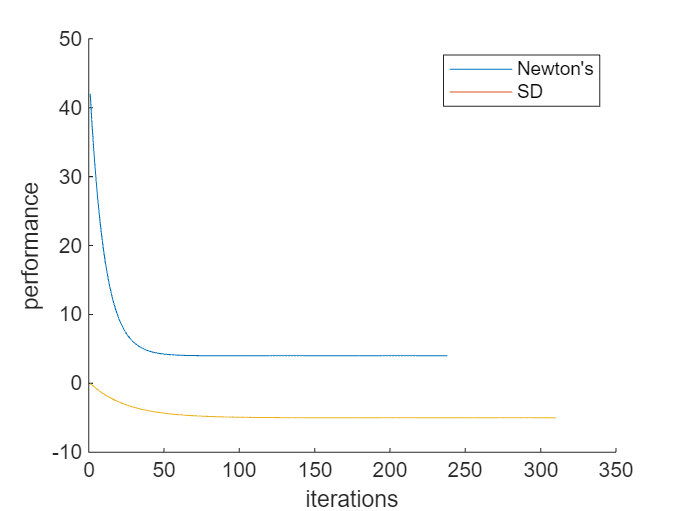

figure;
hold on;

plot(1:length(w_Newton_M),g_vec(w_Newton_M));
plot(1:length(w_SD_M),w_SD_M);

xlabel("iterations")
ylabel("performance")
legend("Newton's",'SD')
hold off;

f1 = @(k) 4 + 0.5 .* (0.9).^(2.*k) + 12.5 .* (0.7).^(2.*k);
f2 = @(k) 4 + 38 .* (0.9).^(2.*k);
K = 1:25;
F1 = f1(K);
F2 = f2(K)

F2 =    34.7800   28.9318   24.1948   20.3578   17.2498   14.7323   12.6932   11.0415    9.7036    8.6199    7.7421    7.0311    6.4552    5.9887    5.6109    5.3048    5.0569    4.8561    4.6934    4.5617    4.4550    4.3685    4.2985    4.2418    4.1958


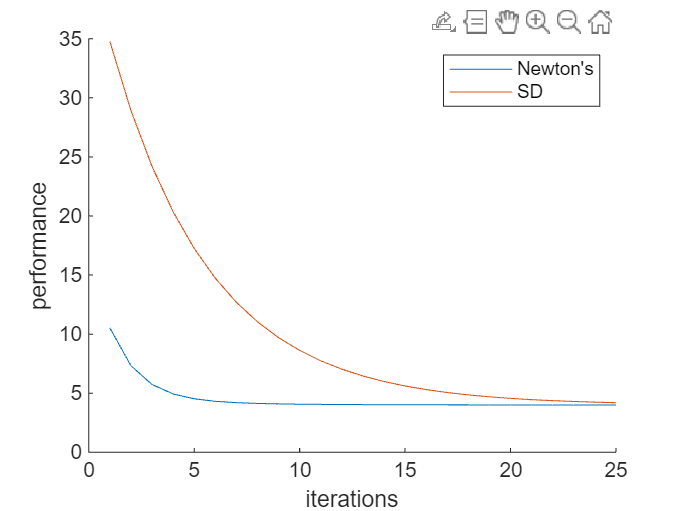


figure;
hold on ;

plot(K,F1(K))
plot(K,F2(K))

xlabel("iterations")
ylabel("performance")
legend("Newton's",'SD')

hold off ;

**3.b**

p = @(x) 5.*x.^2 -20.*x + 23 

p = function_handle with value:
    @(x)5.*x.^2-20.*x+23



x1 = 2.5;
p1 = p(x1)

p1 = 4.2500


x2 = 1.5;
p2 = p(x2)

p2 = 4.2500


x3 = 3.5;
p3 = p(x3)

p3 = 14.2500


l1 = @(x) 4.25 + (x-2.5).*5

l1 = function_handle with value:
    @(x)4.25+(x-2.5).*5


l2 = @(x) 5 + 4.25 + (x-2.5).*5

l2 = function_handle with value:
    @(x)5+4.25+(x-2.5).*5


X = linspace(0,4,1000)

X =          0    0.0040    0.0080    0.0120    0.0160    0.0200    0.0240    0.0280    0.0320    0.0360    0.0400    0.0440    0.0480    0.0521    0.0561    0.0601    0.0641    0.0681    0.0721    0.0761    0.0801    0.0841    0.0881    0.0921    0.0961    0.1001    0.1041    0.1081    0.1121    0.1161    0.1201    0.1241    0.1281    0.1321    0.1361    0.1401    0.1441    0.1481    0.1522    0.1562    0.1602    0.1642    0.1682    0.1722    0.1762    0.1802    0.1842    0.1882    0.1922    0.1962


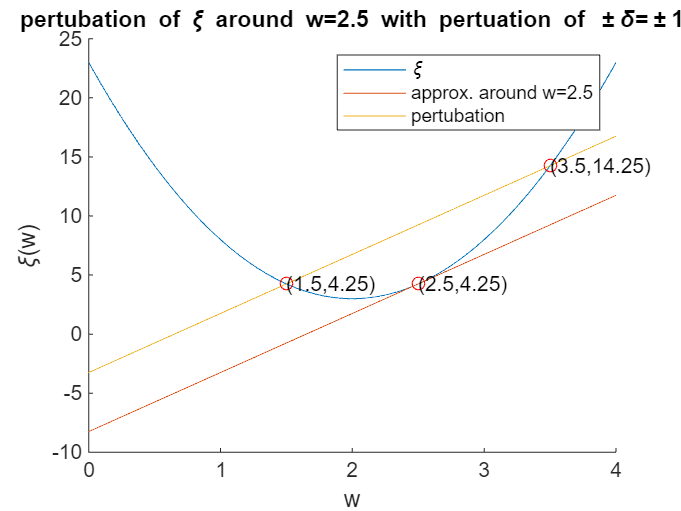

figure; 
hold on ; 

plot(X,p(X))
plot(X,l1(X))
plot(X,l2(X))
plot(x1,p1,"or")
text(x1, p1, '(2.5,4.25)')
plot(x2,p2,"or")
text(x2, p2, '(1.5,4.25)')
plot(x3,p3,"or")
text(x3, p3, '(3.5,14.25)')
legend("\xi","approx. around w=2.5","pertubation")
xlabel("w")
ylabel("\xi(w)")

title("pertubation of \xi around w=2.5 with pertuation of \pm\delta=\pm1")
hold off ;

POST LAB

addpath("./");

%% Lab Report Analysis using SD_LMS
clear; clc; close all;

% --- 1. Signal Setup ---
Ln = 200;                  % Number of iterations
k = 1:Ln;                  % Time index
x1 = cos(2*pi*k/16);       % Input 1
x2 = sin(2*pi*k/16);       % Input 2
InSig = [x1; x2];          % Formatted for MultiRef (2 rows)
RefSig = cos(2*pi*k/16 + pi/2); % Desired Response

% Theoretical optimal weights for comparison
w_opt = [0; -1];

%% --- Part B.1: Testing Step Size (Mu / U) ---
% We will test a small, optimal, and overly large U
U_small = 0.01;
U_opt   = 0.1;
U_large = 1.1; % May cause instability/oscillation depending on R eigenvalues

Win_default = [0; 0];

% Run the function for different U values
[~, WConv_s, Er_s] = SD_LMS(Win_default, InSig, RefSig, U_small);
[~, WConv_o, Er_o] = SD_LMS(Win_default, InSig, RefSig, U_opt);
[~, WConv_l, Er_l] = SD_LMS(Win_default, InSig, RefSig, U_large);


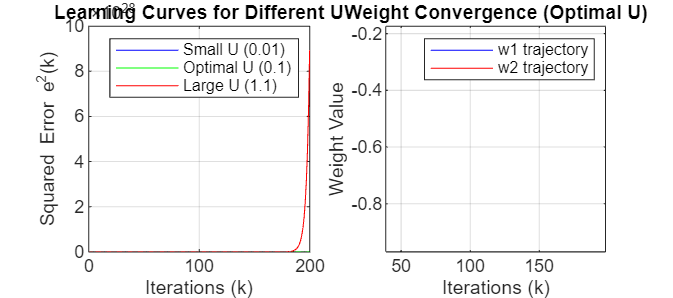

% Plotting Step Size Effects
figure('Name', 'Effect of Step Size (U)', 'Position', [100, 100, 900, 400]);

% Learning Curves (Error Squared)
subplot(1, 2, 1);
plot(k, Er_s.^2, 'b', k, Er_o.^2, 'g', k, Er_l.^2, 'r');
title('Learning Curves for Different U');
xlabel('Iterations (k)');
ylabel('Squared Error e^2(k)');
legend('Small U (0.01)', 'Optimal U (0.1)', 'Large U (1.1)');
grid on;

% Weight Trajectories (for Optimal U)
subplot(1, 2, 2);
plot(k, WConv_o(1,:), 'b', k, WConv_o(2,:), 'r');
hold on;
yline(w_opt(1), 'b--', 'w1 Optimal');
yline(w_opt(2), 'r--', 'w2 Optimal');
title('Weight Convergence (Optimal U)');
xlabel('Iterations (k)');
ylabel('Weight Value');
legend('w1 trajectory', 'w2 trajectory');
grid on;

%% --- Part B.2: Testing Initial Conditions ---
% We will use the optimal U but start from three different places

Win_1 = [0; 0];     % Origin
Win_2 = [2; 1];     % Far positive
Win_3 = [-2; -3];   % Far negative

[~, WConv_ic1, Er_ic1] = SD_LMS(Win_1, InSig, RefSig, U_opt);
[~, WConv_ic2, Er_ic2] = SD_LMS(Win_2, InSig, RefSig, U_opt);
[~, WConv_ic3, Er_ic3] = SD_LMS(Win_3, InSig, RefSig, U_opt);


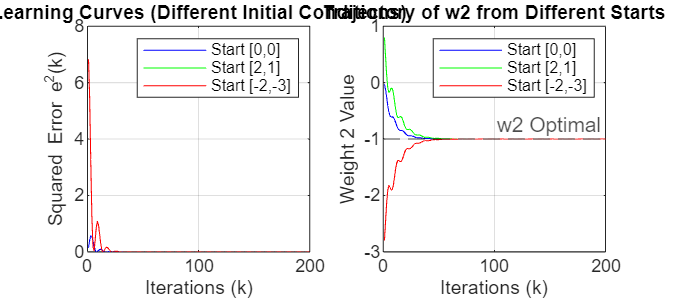

% Plotting Initial Conditions Effects
figure('Name', 'Effect of Initial Conditions', 'Position', [150, 150, 900, 400]);

% Learning Curves
subplot(1, 2, 1);
plot(k, Er_ic1.^2, 'b', k, Er_ic2.^2, 'g', k, Er_ic3.^2, 'r');
title('Learning Curves (Different Initial Conditions)');
xlabel('Iterations (k)');
ylabel('Squared Error e^2(k)');
legend('Start [0,0]', 'Start [2,1]', 'Start [-2,-3]');
grid on;

% Weight 2 Trajectory Comparison
subplot(1, 2, 2);
plot(k, WConv_ic1(2,:), 'b', k, WConv_ic2(2,:), 'g', k, WConv_ic3(2,:), 'r');
hold on;
yline(w_opt(2), 'k--', 'w2 Optimal');
title('Trajectory of w2 from Different Starts');
xlabel('Iterations (k)');
ylabel('Weight 2 Value');
legend('Start [0,0]', 'Start [2,1]', 'Start [-2,-3]');
grid on;

Excess_MSE_exp = mean(Er_o(end-50:end).^2);

Excess_MSE_exp = 1.6365e-16

% Assuming you ran the simulation and have WConv_o (optimal weights over time)
% and your theoretical optimal weights are w_opt = [0; -1]

Ln = length(WConv_o);
w_opt = [0; -1];

% 1. Calculate the squared weight error for every iteration
Weight_Error_Sq = zeros(1, Ln);
for k = 1:Ln
    Weight_Error_Sq(k) = norm(WConv_o(:, k) - w_opt)^2;
end

% 2. Find initial value
Initial_Error = Weight_Error_Sq(1);

% 3. Calculate thresholds
Tau_Threshold = Initial_Error * exp(-1); % 1/e (~36.8%)
Settling_Threshold = Initial_Error * 0.02; % 2% for steady-state

% 4. Numerically find the time constants
% Find the FIRST iteration where the error drops below the threshold
tau_MSE_exp = find(Weight_Error_Sq <= Tau_Threshold, 1);

% Find the iteration where the error drops and STAYS below 2%
% (find the LAST time it was above the threshold, and add 1)
T_MSE_exp = find(Weight_Error_Sq > Settling_Threshold, 1, 'last') + 1;

% Display results
fprintf('--- Time Constants (Numerical vs Analytical for U=0.1) ---\n');

--- Time Constants (Numerical vs Analytical for U=0.1) ---


fprintf('Experimental tau_MSE: %d iterations\n', tau_MSE_exp);

Experimental tau_MSE: 5 iterations


fprintf('Analytical tau_MSE:   %d iterations\n', 1 / (2 * U_opt));

Analytical tau_MSE:   5 iterations


fprintf('Experimental T_MSE:   %d iterations\n', T_MSE_exp);

Experimental T_MSE:   19 iterations


fprintf('Analytical T_MSE:     %d iterations\n', 2 / U_opt);

Analytical T_MSE:     20 iterations


PART 1.d)

%% Section D: Newton-LMS Analysis
clear; clc; close all;

% 1. Signal Setup
Ln = 200;                  
k = 1:Ln;                  
x1 = cos(2*pi*k/16);       
x2 = sin(2*pi*k/16);       
InSig = [x1; x2];          
RefSig = cos(2*pi*k/16 + pi/2); 

% 2. Algorithm Parameters
Win = [0; 0];
U = 0.05;   % Convergence rate
dN = 16;    % Estimate R every 16 samples (1 full period)

% Analytical R matrix (calculated in part a)
R_analytical = [0.5, 0; 0, 0.5];

% 3. Run the algorithms
% Run 1: Newton LMS with Analytical R
[Wout_na, WConv_na, Er_na, Rout_na] = NEW_LMS(Win, InSig, RefSig, U, R_analytical, dN);

% Run 2: Newton LMS with Estimated R (pass empty R to trigger estimation)
[Wout_ne, WConv_ne, Er_ne, Rout_ne] = NEW_LMS(Win, InSig, RefSig, U, [], dN);

a = 16

Rt1 =     0.5000   -0.0000
   -0.0000    0.5000


a = 32

Rt1 =     0.5000    0.0000
    0.0000    0.5000


a = 48

Rt1 =     0.5000    0.0000
    0.0000    0.5000


a = 64

Rt1 =     0.5000   -0.0000
   -0.0000    0.5000


a = 80

Rt1 =     0.5000   -0.0000
   -0.0000    0.5000


a = 96

Rt1 =     0.5000   -0.0000
   -0.0000    0.5000


a = 112

Rt1 =     0.5000    0.0000
    0.0000    0.5000


a = 128

Rt1 =     0.5000   -0.0000
   -0.0000    0.5000


a = 144

Rt1 =     0.5000    0.0000
    0.0000    0.5000


a = 160

Rt1 =     0.5000   -0.0000
   -0.0000    0.5000


a = 176

Rt1 =     0.5000    0.0000
    0.0000    0.5000


a = 192

Rt1 =     0.5000   -0.0000
   -0.0000    0.5000


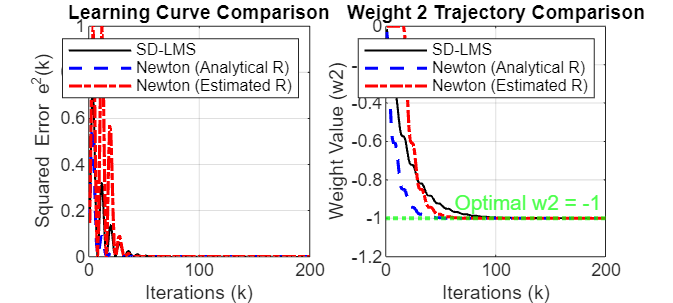


% Run 3: SD-LMS (for comparison)
% Note: To make a fair comparison, the effective step size in SD_LMS 
% should match the Newton step size. Newton uses 2*U*R^-1.
[~, WConv_sd, Er_sd] = SD_LMS(Win, InSig, RefSig, U);

% 4. Plotting the Comparison
figure('Name', 'Newton-LMS Comparisons', 'Position', [100, 100, 1000, 450]);

% --- Plot A: Learning Curves ---
subplot(1, 2, 1);
plot(k, Er_sd.^2, 'k', 'LineWidth', 1); hold on;
plot(k, Er_na.^2, 'b--', 'LineWidth', 1.5);
plot(k, Er_ne.^2, 'r-.', 'LineWidth', 1.5);
title('Learning Curve Comparison');
xlabel('Iterations (k)');
ylabel('Squared Error e^2(k)');
legend('SD-LMS', 'Newton (Analytical R)', 'Newton (Estimated R)');
grid on;

% --- Plot B: Weight Trajectories (w2) ---
subplot(1, 2, 2);
plot(k, WConv_sd(2,:), 'k', 'LineWidth', 1); hold on;
plot(k, WConv_na(2,:), 'b--', 'LineWidth', 1.5);
plot(k, WConv_ne(2,:), 'r-.', 'LineWidth', 1.5);
yline(-1, 'g:', 'Optimal w2 = -1', 'LineWidth', 2);
title('Weight 2 Trajectory Comparison');
xlabel('Iterations (k)');
ylabel('Weight Value (w2)');
legend('SD-LMS', 'Newton (Analytical R)', 'Newton (Estimated R)');
grid on;

Part 2 : ANC

%% Section 2: Narrowband Noise Cancellation
clear; clc; close all;

% 1. Load Speech Signal
% Make sure you have a .wav file in your directory
[s, Fs] = audioread('female_speech.wav'); 
s = s(:,1)'; % Ensure it is a row vector and mono
t = (0:length(s)-1) / Fs; % Time vector

% 2. Calculate Powers and Alpha for SNR = -30dB
P_speech = mean(s.^2);
P_noise_req = P_speech * 1000; % From the -30dB calculation
alpha = sqrt(2 * P_noise_req);

% 3. Generate the Noise Signal n(t)
omega = 250 * 2 * pi;
phi = pi/4; % Unknown arbitrary phase
% Generate the 10Hz triangle wave between -pi/2 and pi/2
% The '0.5' makes it a symmetric triangle wave
theta_t = (pi/2) * sawtooth(2 * pi * 10 * t, 0.5); 

n = alpha * sin(omega * t + theta_t + phi);

% The noisy input to the filter
x = s + n; 

% 4. Generate the Reference Signal r(t)
alpha_tilde = 1; % Chosen arbitrary amplitude
phi_tilde = 0;   % Chosen arbitrary phase
r = alpha_tilde * sin(omega * t + theta_t + phi_tilde);

% 5. Adaptive Filtering using SD_LMS
% Format variables for the function
InSig = r;       % The reference signal goes into the filter
RefSig = x;      % The noisy signal is what we try to match

U = 0.01;        % Step size
num_weights = 20; 
Win = zeros(num_weights, 1); % Initial weights

% Run the algorithm
[Wout, WConv, Er] = SD_LMS(Win, InSig, RefSig, U);

% THE MAGIC: The error signal 'Er' IS the cleaned speech!
s_hat = Er; 


% 6. Playing noisy audio
sound(x, Fs); 

% Playing denoised audio
sound(s_hat, Fs); 
% The sound track says : "dont ask me to carry an oiley rag like that"

2.c)

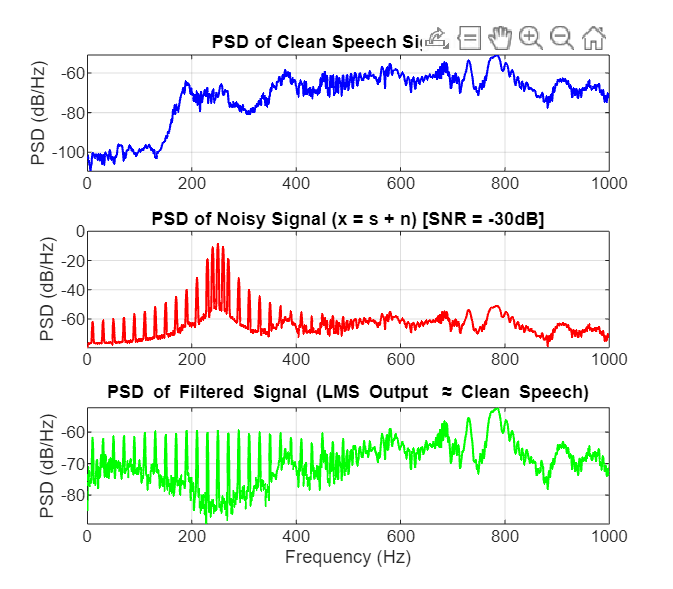

%% Section C: Power Spectral Density (PSD) Analysis
% Make sure s, x, s_hat, and Fs are in your workspace from the previous part

figure('Name', 'Power Spectral Density Comparison', 'Position', [100, 100, 800, 700]);

% --- 1. PSD of Clean Original Speech ---
subplot(3, 1, 1);
% Using default pwelch windows/overlap, but explicitly passing Fs for Hz axis
[pxx_s, f_s] = pwelch(s, [], [], [], Fs); 
plot(f_s, 10*log10(pxx_s), 'b', 'LineWidth', 1);
title('PSD of Clean Speech Signal (s)');
ylabel('PSD (dB/Hz)');
% The prompt asks to zoom into the relevant range. 
% Speech is mostly 0-4000Hz, and the noise is at 250Hz.
xlim([0 1000]); 
grid on;

% --- 2. PSD of Noisy Signal (SNR = -30dB) ---
subplot(3, 1, 2);
[pxx_x, f_x] = pwelch(x, [], [], [], Fs);
plot(f_x, 10*log10(pxx_x), 'r', 'LineWidth', 1);
title('PSD of Noisy Signal (x = s + n) [SNR = -30dB]');
ylabel('PSD (dB/Hz)');
xlim([0 1000]); % Keep axes consistent for comparison
grid on;

% --- 3. PSD of Filtered Signal ---
subplot(3, 1, 3);
[pxx_shat, f_shat] = pwelch(s_hat, [], [], [], Fs);
plot(f_shat, 10*log10(pxx_shat), 'g', 'LineWidth', 1);
title('PSD of Filtered Signal (LMS Output \approx Clean Speech)');
xlabel('Frequency (Hz)');
ylabel('PSD (dB/Hz)');
xlim([0 1000]); % Keep axes consistent for comparison
grid on;

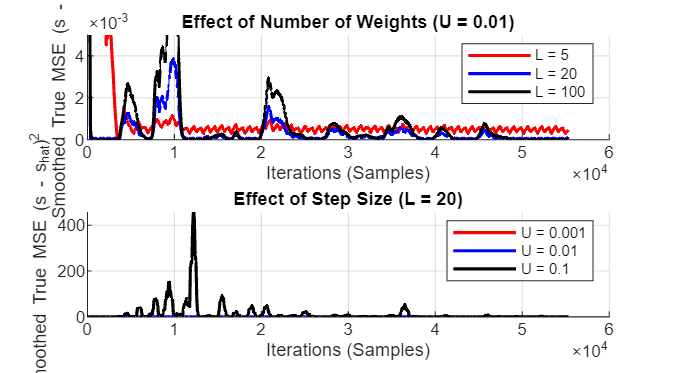

%% Section D: Parameter Sweep (Weights and Step Size)
% Assuming 's' (clean speech), 'x' (noisy speech), and 'r' (reference) are loaded

% --- Experiment 1: Effect of Number of Weights ---
U_fixed = 0.01;
weights_to_test = [5, 20, 100];
figure('Name', 'Effect of Filter Length and Step Size', 'Position', [100, 100, 900, 500]);

subplot(2, 1, 1 );
hold on;
colors = {'r', 'b', 'k'};
for i = 1:length(weights_to_test)
    L = weights_to_test(i);
    Win = zeros(L, 1);
    [~, ~, s_hat] = SD_LMS(Win, r, x, U_fixed);
    
    % Calculate true error between clean speech and filter output
    true_error = (s - s_hat).^2;
    % Use a moving average to smooth the curve for visualization
    smoothed_error = movmean(true_error, 500); 
    
    plot(smoothed_error, colors{i}, 'LineWidth', 1.5);
end
title('Effect of Number of Weights (U = 0.01)');
xlabel('Iterations (Samples)');
ylabel('Smoothed True MSE (s - s_{hat})^2');
legend('L = 5', 'L = 20', 'L = 100');
ylim([0 0.005 ])
grid on;

% --- Experiment 2: Effect of Step Size ---
L_fixed = 20;
Win_fixed = zeros(L_fixed, 1);
U_to_test = [0.005, 0.01, 0.1];

subplot(2, 1, 2);
hold on;
for i = 1:length(U_to_test)
    U = U_to_test(i);
    [~, ~, s_hat] = SD_LMS(Win_fixed, r, x, U);
    
    true_error = (s - s_hat).^2;
    smoothed_error = movmean(true_error, 500); 
    
    plot(smoothed_error, colors{i}, 'LineWidth', 1.5);
end
title('Effect of Step Size (L = 20)');
xlabel('Iterations (Samples)');
ylabel('Smoothed True MSE (s - s_{hat})^2');
legend('U = 0.001', 'U = 0.01', 'U = 0.1');

grid on;

part 3.a)

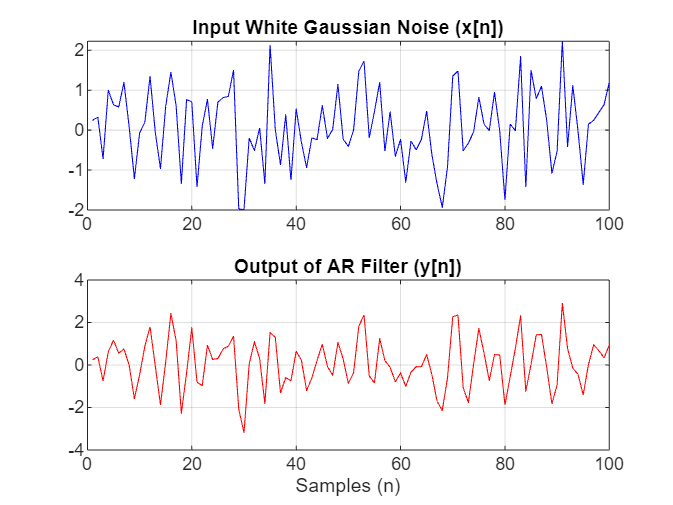

addpath("./")
%% Part 3: System Identification
% Section A: Synthesizing the AR system output
clear; clc; close all;

% Define the number of samples 
% (10,000 is a good starting point to give the LMS time to learn later)
N = 10000; 

% 1. Generate Gaussian White Noise input x[n]
% 'randn' generates normally distributed (Gaussian) random numbers 
% with a mean of 0 and variance of 1.
x = randn(N, 1)'; 

% 2. Define the AR filter coefficients
% Denominator coefficients 'a' as given in the prompt
a = [1, -0.25, 0.5]; 
% Since it is a purely autoregressive (AR) model, the numerator 'b' is simply 1
b = 1; 

% 3. Synthesize the output signal y[n] 
y = filter(b, a, x);

% Optional: Plot a small snippet to verify it worked
figure('Name', 'System Identification - Signals');
subplot(2,1,1);
plot(x(1:100), 'b'); 
title('Input White Gaussian Noise (x[n])');
grid on;

subplot(2,1,2);
plot(y(1:100), 'r'); 
title('Output of AR Filter (y[n])');
xlabel('Samples (n)');
grid on;

3.b)

addpath('./')
%% Block 1: Setup the System
%% Block 1: Setup the System (Row Vectors)
clear; clc; close all;

N = 10000; 

% Generate input explicitly as a 1xN row vector
x = randn(1, N); 

% Generate true system output
a_true = [1, -0.25, 0.5];
% Since x is 1xN, filter will output y as a 1xN row vector automatically
y = filter(1, a_true, x);

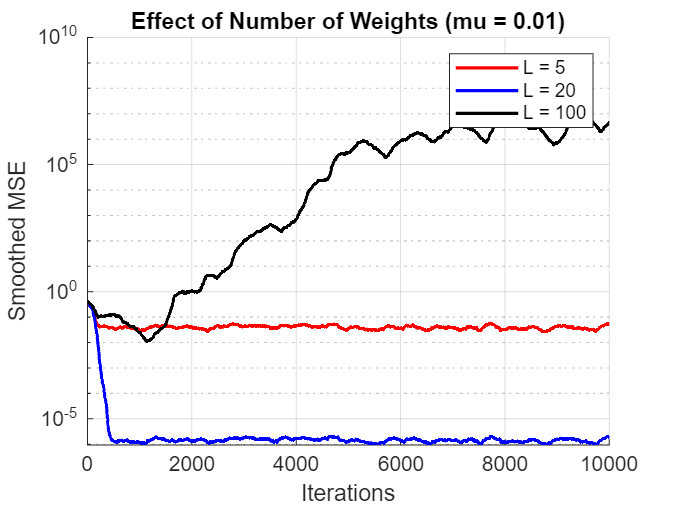

%% Block 2: Sweep 1 - Effect of Number of Weights (L) (FIXED)
mu_fixed = 0.01;
L_test = [5, 20, 100];
colors = {'r', 'b', 'k'};

figure('Name', 'System ID - Number of Weights');
hold on; title('Effect of Number of Weights (mu = 0.01)');

for i = 1:length(L_test)
    L = L_test(i);
    w_init = zeros(L, 1); % Column vector for initial weights
    
    % FIXED: Grabbing the THIRD output (Er) instead of the second (WConv)
    [~, ~, e] = SD_LMS(w_init, x, y, mu_fixed);
    
    plot(movmean(e.^2, 200), colors{i}, 'LineWidth', 1.5);
end

xlabel('Iterations'); 
ylabel('Smoothed MSE'); 
set(gca, 'YScale', 'log');
legend('L = 5', 'L = 20', 'L = 100'); 
grid on;

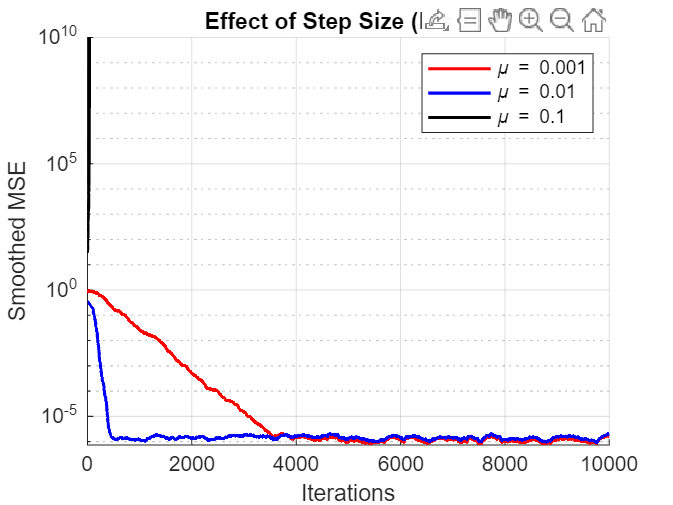

%% Block 3: Sweep 2 - Effect of Step Size (mu)
L_fixed = 20; % Locking L to 20 based on previous success
mu_test = [0.001, 0.01, 0.1];
colors = {'r', 'b', 'k'};

figure('Name', 'System ID - Step Size');
hold on; title('Effect of Step Size (L = 20)');

for i = 1:length(mu_test)
    mu = mu_test(i);
    w_init = zeros(L_fixed, 1); % Initial weights
    
    % Call SD_LMS with our row vectors (x and y) and the current mu
    [~, ~, e] = SD_LMS(w_init, x, y, mu);
    
    plot(movmean(e.^2, 200), colors{i}, 'LineWidth', 1.5);
end

xlabel('Iterations'); 
ylabel('Smoothed MSE'); 
ylim([0 1e10])
set(gca, 'YScale', 'log');
legend('\mu = 0.001', '\mu = 0.01', '\mu = 0.1'); 
grid on;

%% Block 4: AR Coefficient Estimation & Initial Conditions
L = 20; 
mu = 0.01;

% --- Test 1: Zero Initial Conditions ---
w_init_zero = zeros(L, 1);
[Wout_zero, ~, ~] = SD_LMS(w_init_zero, x, y, mu);

% --- Test 2: Random Initial Conditions ---
w_init_rand = randn(L, 1); % Random starting guess instead of zeros
[Wout_rand, ~, ~] = SD_LMS(w_init_rand, x, y, mu);

% --- Extract AR Coefficients from FIR Weights (from Test 1) ---
% The FIR weights approximate the impulse response h[n]
h0 = Wout_zero(1);
h1 = Wout_zero(2);
h2 = Wout_zero(3);

% Using the difference equation to solve for a1 and a2
a1_est = -h1 / h0;
a2_est = -(h2 + a1_est * h1) / h0;

% Display Results in Command Window
disp('--- Original System Coefficients ---');

--- Original System Coefficients ---


disp('a1 = -0.25, a2 = 0.5');

a1 = -0.25, a2 = 0.5



disp('--- Estimated Coefficients (Zero Init) ---');

--- Estimated Coefficients (Zero Init) ---


fprintf('a1_est = %.4f\n', a1_est);

a1_est = -0.2501


fprintf('a2_est = %.4f\n', a2_est);

a2_est = 0.4999


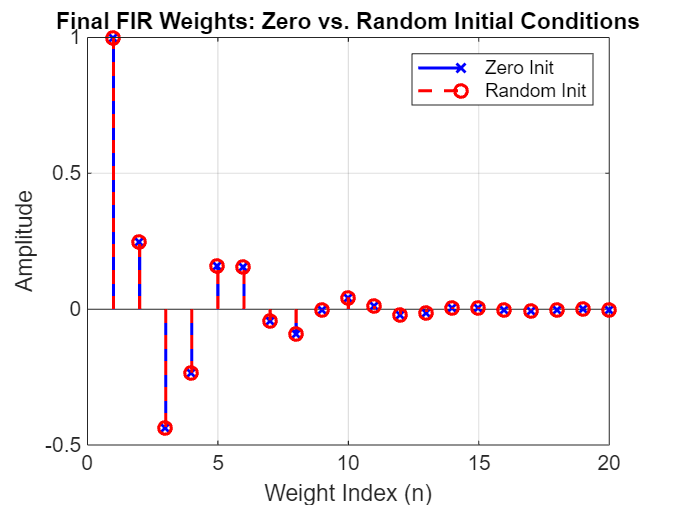


% Plot to compare the final weights
figure('Name', 'Effect of Initial Conditions');
stem(1:L, Wout_zero, 'bx', 'LineWidth', 1.5); hold on;
stem(1:L, Wout_rand, 'r--', 'LineWidth', 1.5);
title('Final FIR Weights: Zero vs. Random Initial Conditions');
xlabel('Weight Index (n)'); ylabel('Amplitude');
legend('Zero Init', 'Random Init'); grid on;

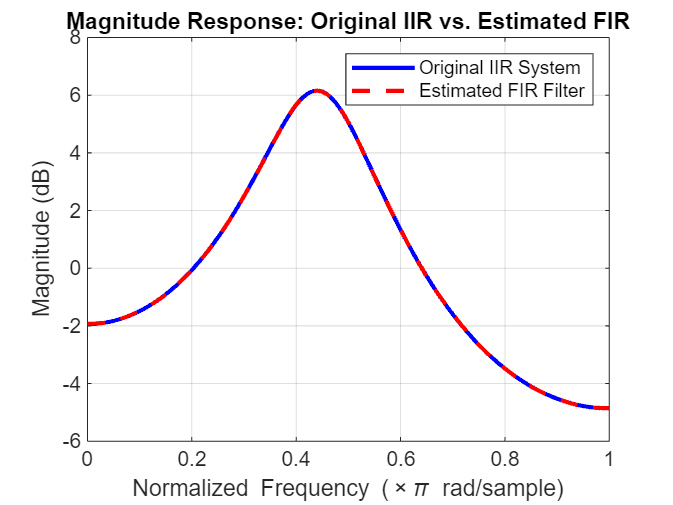

%% Block 5: Transfer Function Comparison (Section c)
% 1. Define the original IIR filter coefficients
b_true = 1; 
a_true = [1, -0.25, 0.5]; 

% 2. Define the estimated FIR filter coefficients (from Block 4)
b_est = Wout_zero; 
a_est = 1; 

% 3. Calculate frequency responses using freqz
nfft = 1024; % Number of frequency points for a smooth line
[H_true, w] = freqz(b_true, a_true, nfft);
[H_est, ~] = freqz(b_est, a_est, nfft);

% 4. Plot the Magnitude Responses
figure('Name', 'Transfer Function Comparison');
plot(w/pi, 20*log10(abs(H_true)), 'b', 'LineWidth', 2); hold on;
plot(w/pi, 20*log10(abs(H_est)), 'r--', 'LineWidth', 2);

title('Magnitude Response: Original IIR vs. Estimated FIR');
xlabel('Normalized Frequency (\times\pi rad/sample)');
ylabel('Magnitude (dB)');
legend('Original IIR System', 'Estimated FIR Filter');
grid on;